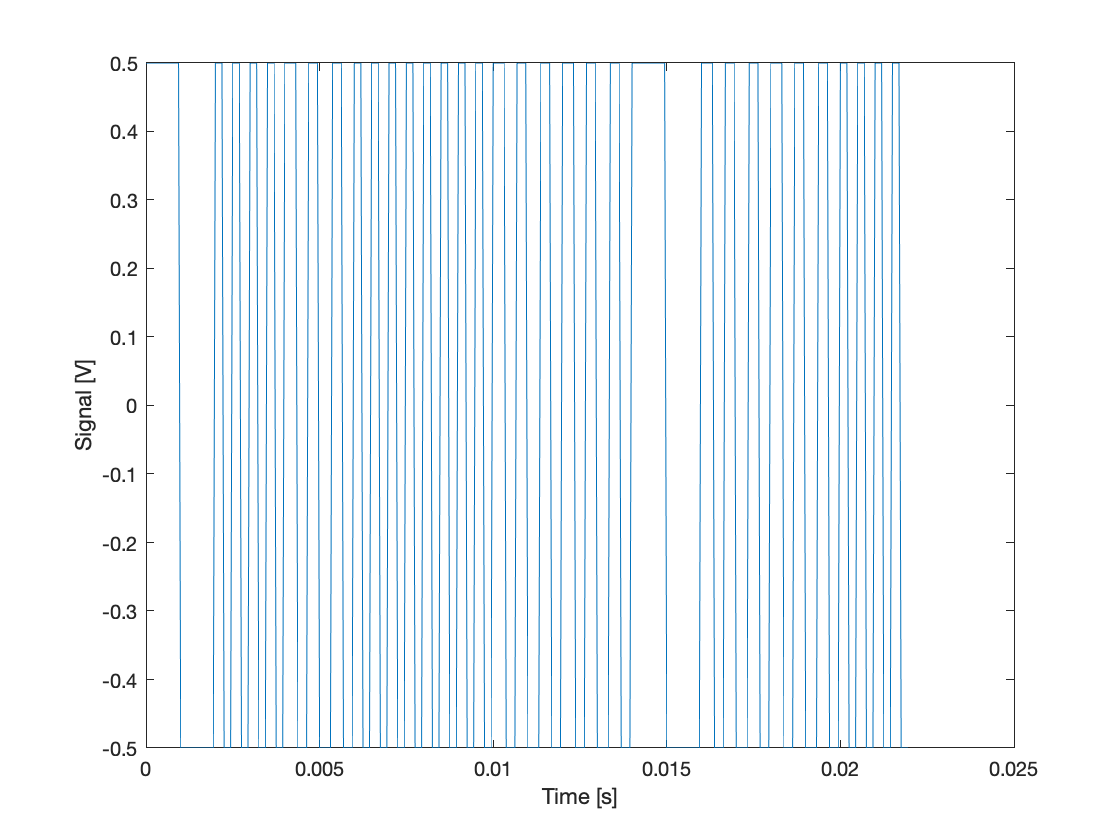

close all;
clearvars;



fs = 16000; % 16K

f1 = 2000;
f2 = 1500;

f3 = 500;
f4 = 1000;

t0 = 0:1/fs:0.002-1/fs;
v1 = (square(2*pi*t0*f1)+1)/2-0.5; % 1
v2 = (square(2*pi*t0*f2)+1)/2-0.5; % 0
v3 = (square(2*pi*t0*f3)+1)/2-0.5; % sych frame
v4 = (square(2*pi*t0*f4)+1)/2-0.5; % post frame

dv1 = [diff(v1),1];
dv2 = [diff(v2),1];
dv3 = [diff(v3),1];

v = [v3,v1,v2,v1,v1,v2,v2,v3,v2,v2,v1]; %101100 001
dv = diff(v);
dv = [dv,1];
% x = v;
t = 0:1/fs:0.002*length(v)/length(v1)-1/fs;
x = v;
% t = t(2:end);
n = 32;

a = buffer(x,n,n-1); % overlap . padding in the beginning but not the end

i = 1;
y_want = [];
coe = [];

while i < length(a(1,:))+1
    R = sum(a(:,i).*dv3');
%     R = corrcoef(a(:,i), dv3');
    coe= [coe; R];
    Y = fft(a(:,i), n);
    P = abs(Y/n).^2;
    P1= P(1:n/2+1);
    y_want = [y_want; P1(3), P1(5), P1(6)];
    i = i +1;
end

f_plot = fs*(0:(n/2))/n;



plot(t, x);
xlabel("Time [s]")
ylabel("Signal [V]")

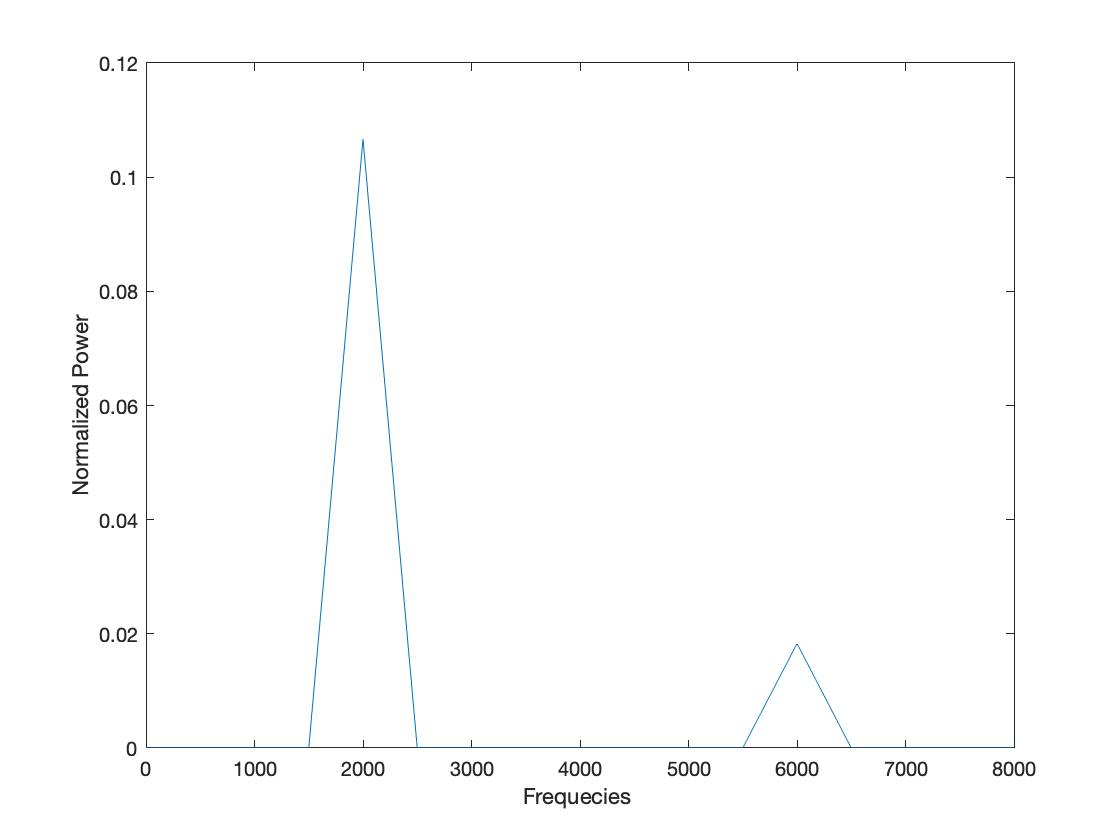



plot(f_plot, P1);
xlabel("Frequecies ")
ylabel("Normalized Power")

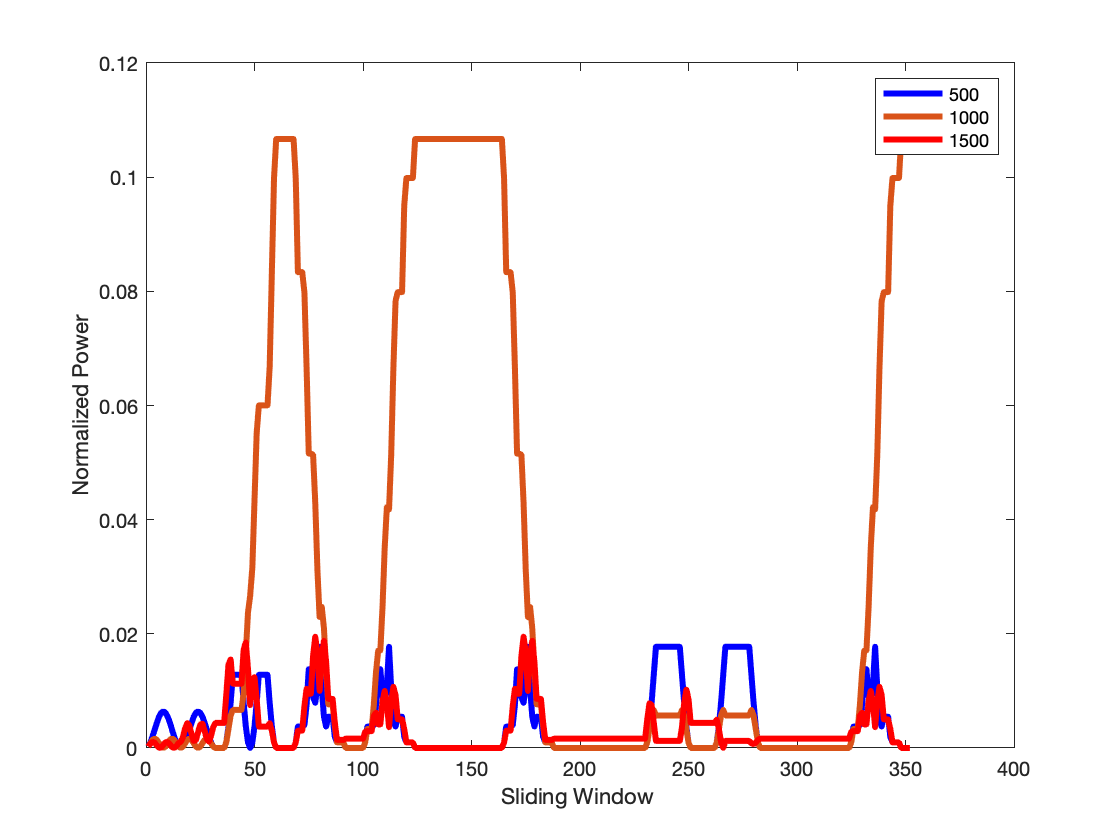


plot(1:length(y_want), y_want(:,1), 'b', 'LineWidth',3);
hold on
plot(1:length(y_want), y_want(:,2), 'LineWidth',3);
hold on
plot(1:length(y_want), y_want(:,3), 'r', 'LineWidth',3);
hold off;

legend('500', '1000', '1500');
% legend('0.5k', '1k');
xlabel("Sliding Window ");
ylabel("Normalized Power");

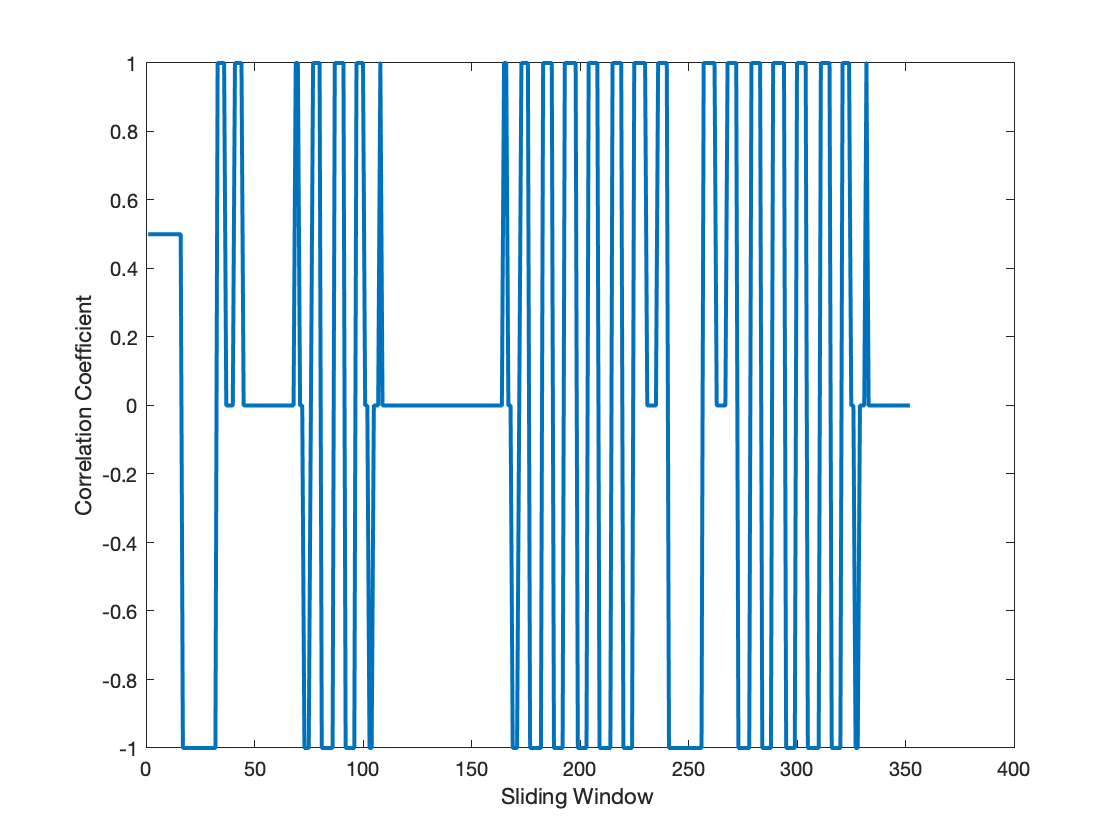


plot(1:length(coe), coe, 'LineWidth',2);
xlabel("Sliding Window ");
ylabel("Correlation Coefficient");


result = y_want(:,1) < y_want(:,2);
